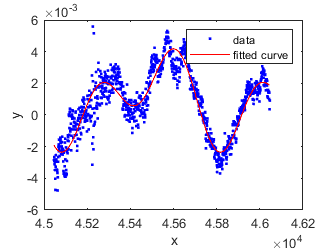

clear;
clc;

[x, Fs] = audioread('SignalHW2.wav');
% y=[1:length(x)]';
% plot(x,y)

% y1 = [1:2500]';
% y2 = [2500:5000]';
% f1 = fit(y1,x1,'fourier2');
% f2 = fit(y2,x2,'fourier2');
% plot(f1, y1, x1)
% plot(f2, y2, x2)

vector = [];
incrementCount = 1001;
for a = 1.0 : incrementCount : 46954 - (mod(46954,incrementCount))
x1 = x(a:a+(incrementCount-1));
y1 = [a:a+(incrementCount-1)]';
f1 = fit(y1,x1,'fourier2');
for b = 1.0 : incrementCount
vector(end+1) = f1(b);
end
plot(f1, y1, x1)

end

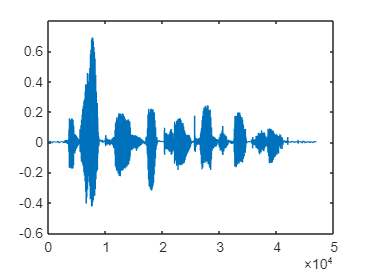


y = vector';
plot(x)

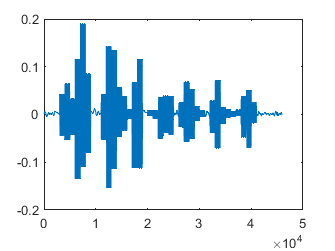

plot(y')

sound(x, Fs)
pause(5);

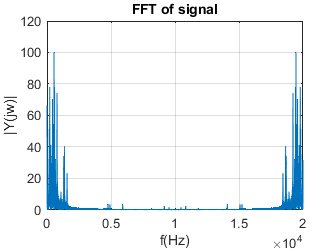

sound(vector, Fs)

Len_y=length(y); p=abs(fft(y)); f=(Fs/Len_y)*(1:Len_y); figure; plot(f,p);
title('FFT of signal'); ylabel('|Y(jw)|'); xlabel('f(Hz)'); grid;